# BPSK Modulator Simulation in MATLAB

## Theoretical background

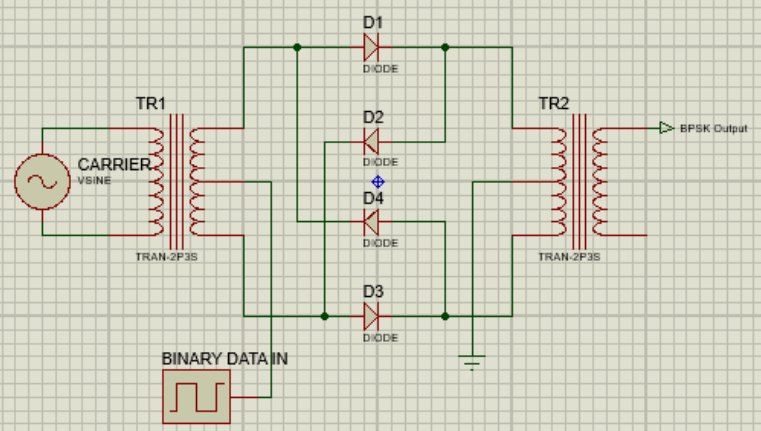

- Above is a BPSK modulator which uses a balanced modulator. 

- The carrier wave is a high frequency sinusoidal wave and the binary data input waveform are square waves of amplitudes +1 V and -1 V corresponding to binary values 1 and 0 respectively. 

- The diodes control the "orientation" of the sine wave that is passed through the transformer TR2. When the binary data input is +1 V, the BPSK output is equal to the carrier wave, or has no phase difference. When the binary data input is - 1 V, the BPSK output and the carrier wave will have a 180-degree phase difference, hence the modulation scheme "BPSK".

- The simulation will assume the transformers TR1 and TR2 specifications to be 1:1 and that there is no voltage drop across the diodes. Hence only the phase of the waveforms shall change.

- Below are the expected waveforms (from [What is Phase Shift Keying (PSK)? BPSK modulation, BPSK demodulation, advantages, disadvantages and applications of PSK - Electronics Coach](https://electronicscoach.com/phase-shift-keying.html)):

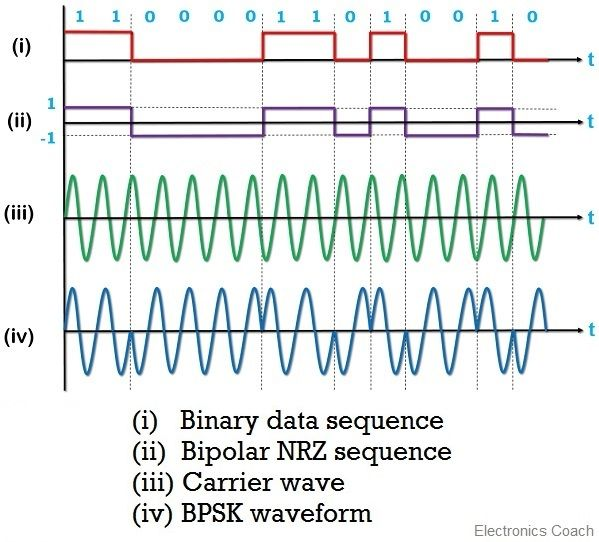

## Simulation of BPSK modulator

### Model the carrier

fc = 1e6;
Ac = 5;

### Generate the time vector

FS = 1e9;
t = linspace(0, 1/fc, fc);

### Model the binary data

bits = '10101001';

### Generate the binary waveforms

bin = zeros(size(bits));
binwave = [];
NRZ = [];
for i = 1 : length(bin)
    if bits(i) == '1'
        bin(i) = 1;
        NRZ = [NRZ ones(1, fc)];
        binwave = [binwave ones(1, fc)];
    elseif bits(i) == '0'
        bin(i) = -1;
        NRZ = [NRZ -ones(1, fc)];
        binwave = [binwave zeros(1, fc)];
    end
end

### Generate the carrier waveform

T = linspace(0, length(bin)/fc, length(bin)*fc);
carrier = Ac.*sin(2*pi*fc*T);

### Generate the complex envelope

cmplx_env = complex(bin);

### Generate the BPSK-modulated waveform

BPSK = [];
for i = 1 : length(bin)
    if bin(i) == 1
        BPSK = [BPSK carrier(1 : fc)];
    else
        BPSK = [BPSK -carrier(1 : fc)];
    end
end

### Display all generated waveforms

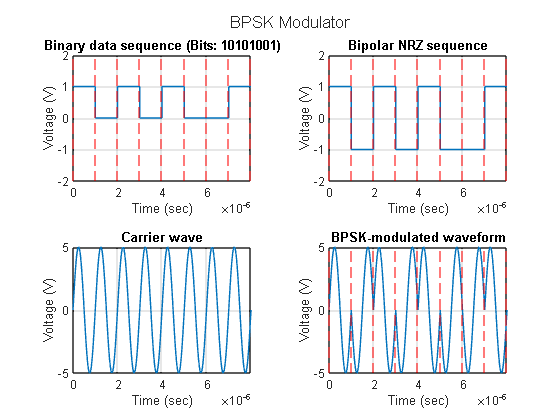

clf
figure(1)
tiledlayout(2, 2)
sgtitle("BPSK Modulator")

nexttile
plot(T, binwave)
title("Binary data sequence (Bits: " + bits + ")")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
ylim([-2 2])
for i = 0 : length(bin), xline(i/fc, LineStyle='--', Color='red'); end
grid on

nexttile
plot(T, NRZ)
title("Bipolar NRZ sequence")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
ylim([-2 2])
for i = 0 : length(bin), xline(i/fc, LineStyle='--', Color='red'); end
grid on

nexttile
plot(T, carrier)
title("Carrier wave")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
grid on

nexttile
plot(T, BPSK)
title("BPSK-modulated waveform")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
for i = 0 : length(bin), xline(i/fc, LineStyle='--', Color='red'); end
grid on

### Plot the BPSK constellation diagram

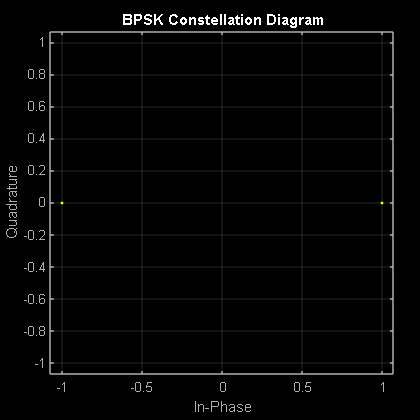

figure(2)
scatterplot(cmplx_env)
title("BPSK Constellation Diagram")
grid on

clear